**伸长比（Re, Elongation ratio）**

活动构造区相对年轻的盆地的形状与山脉的地形坡度呈拉长的形状。由于盆地经历了构造活动减少的地貌演变，拉长的形状往往会转变为更圆形的形状(Bull和McFadden，1977)。因此，细长和圆形流域分别表示活动区域和非活动区域(Canon，1976；Ramirez-Herrera，1998；Figueiredo等人，2019年)。

Re 值是一种无量纲指数，用于比较不同流域盆地中不同程度的构造活动（Rimando和Schoenbohm，2020）。Re 定义为与盆面积相等的圆的直径与盆的最大长度之比，其计算公式为：


$$\mathrm{Re}=\frac{2\left(\sqrt{\frac{A}{\pi }}\right)}{L_b }$$


式中， A 代表了流域的面积，$L_b$ 代表了流域从源头到河口的长度。Re值通常为 0 至 1。Re值越接近 1，表明盆地形状为圆形，地势平坦，坡度平缓，地形起伏较小，存在侧向河道侵蚀，构造作用不活跃。随着Re值的减小，盆地形状变得细长，地形起伏更大，坡度更陡。更长的流域意味着相对的岩石隆起、河道切割和构造活动（Strahler，1964年; Regard等人，2009; Rimando和Schoenbohm，2020）。对于给定的流域，Re值范围<0.5、0.50-0.75和>0.75分别为构造活动、轻微活动和不活动或稳定（Bull和McFadden，1977年; Cuong和Zuchiewicz，2001年）。

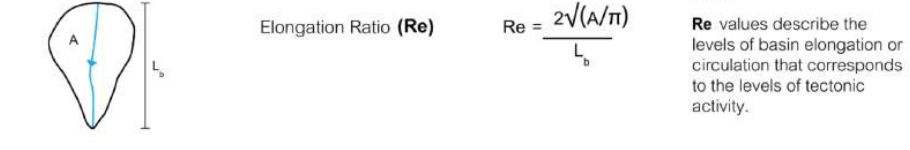

function Re_index = ttb_calculate_re_index(dem, main_stream)
    [main_stream_x, main_stream_y] = STREAMobj2XY(main_stream);
    basin = drainagebasins(FLOWobj(dem));
    [~, basin_x, basin_y] = GRIDobj2polygon(basin);

    % 计算总面积
    total_area = calculate_polygon_area(basin_x, basin_y);

    % 计算河流直线长度
    L_s = get_distance( ...
        main_stream_x(1), main_stream_y(1), ...
        main_stream_x(end-1), main_stream_y(end-1) ...
    );

    Re_index = 2 * sqrt(total_area / pi) / L_s;
end

function area = calculate_polygon_area(polygon_x, polygon_y)
    % 使用叉积公式计算多边形面积
    x = polygon_x(:);
    y = polygon_y(:);

    cross = x(1:end-2) .* y(2:end-1) - x(2:end-1) .* y(1:end-2);
    cross = cross(~isnan(cross));

    area = 0.5 * abs(sum(cross));
end

function distance = get_distance(x1, y1, x2, y2)
    distance = sqrt((x2-x1)^2+(y2-y1)^2);
end